# data extraction

ts = read_log_v13("../LOGS/log1878.csv");

Loaded 55834 samples, t = [0.000, 62.999] s (63.0 s), 4 actuators


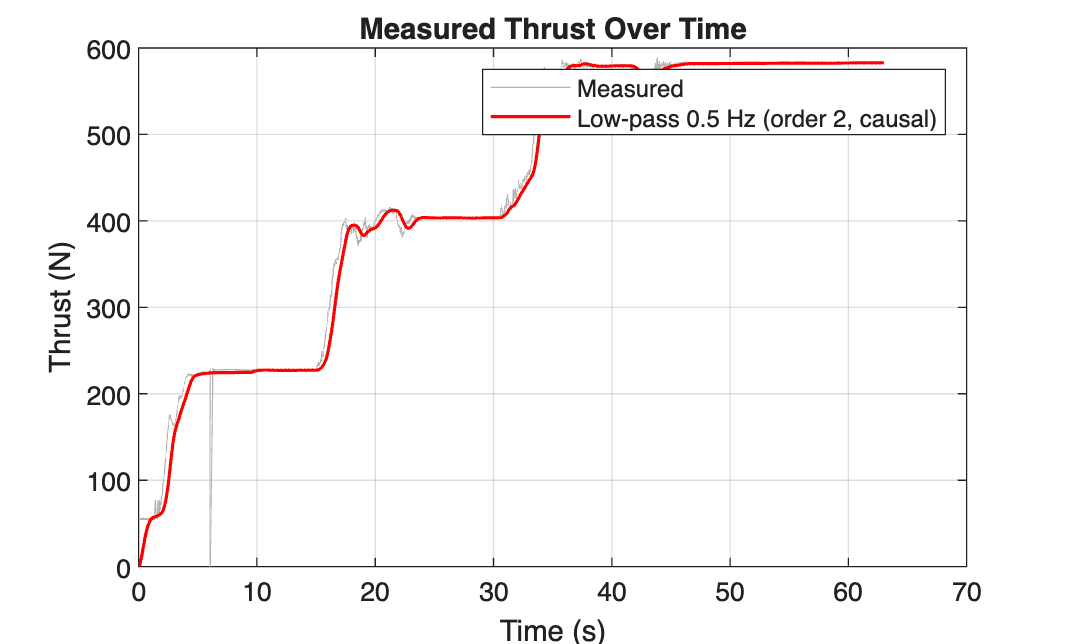


G = 9.80665;
thrust_N = ts.thrust_measured * G;      % convert once

fs = 1/median(diff(ts.t));
fc = 0.5;                                % Hz — set from the PSD, not by feel
assert(fc < fs/2, 'fc (%.1f Hz) exceeds Nyquist (%.1f Hz)', fc, fs/2);

n  = 2;                                 % 2nd order: less ringing on the step
[b,a] = butter(n, fc/(fs/2));

thrust_lp = filter(b, a, thrust_N);     % causal — delay, but no precursor

figure
plot(ts.t, thrust_N, 'Color', [0.7 0.7 0.7]); hold on
plot(ts.t, thrust_lp, 'r', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Thrust (N)');
title('Measured Thrust Over Time'); grid on
legend('Measured', sprintf('Low-pass %g Hz (order %d, causal)', fc, n));


time_filter = ts.t<1.3;
no_load = mean(thrust_N(time_filter))

no_load = 55.0827

## fit function

true_loads = [0 100 200 300];
measured_loads = [55.08 227.27 403.50 582.73];

figure
plot(measured_loads, true_loads)
hold on
fit = polyfit(measured_loads, true_loads,1)

fit =     0.5684  -30.2655


ans = 0.5684

fit = 0.568400949516698 * measured + -30.265519134473056

est_load = fit(1)*measured_loads + fit(2)*ones(size(measured_loads))

est_load =     1.0420   98.9150  199.0843  300.9588


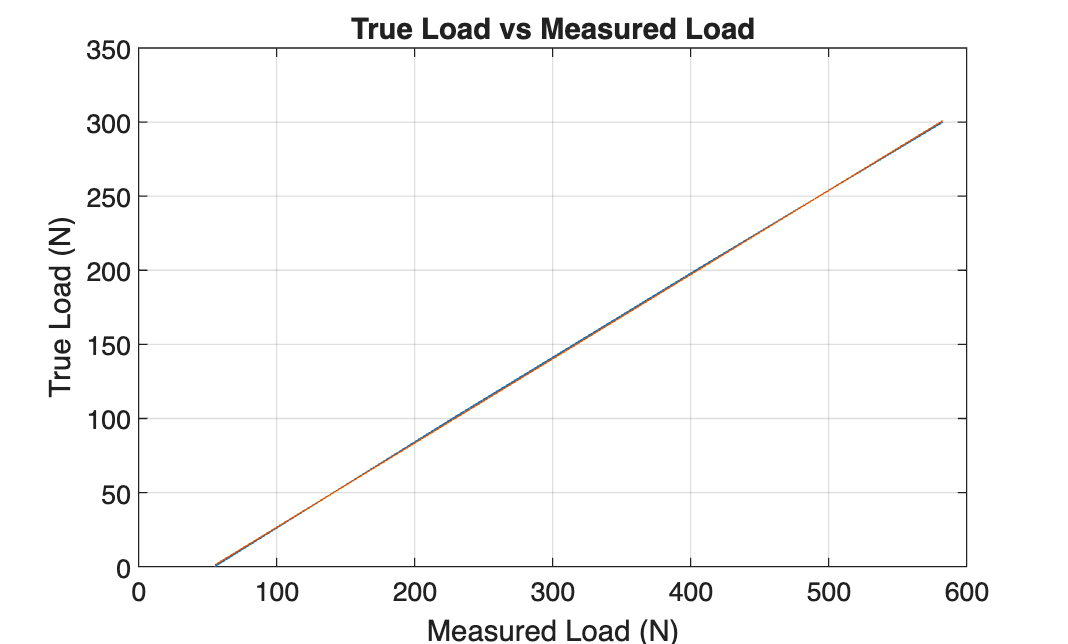

plot(measured_loads, est_load)
ylabel('True Load (N)');
xlabel('Measured Load (N)');
title('True Load vs Measured Load');
grid on;

% axis equal;  % Set equal scaling for both axes
errors = true_loads - est_load

errors =    -1.0420    1.0850    0.9157   -0.9588
